clear;
M = 264.5866;
m = 9.1747;
l = 2.5849;
g_ = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g_*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g_*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
C_ = C(2,:)

C_ =      0     0     1     0


D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];

syms t_ch;
%{
Gamma_f = [0, -0.5, 0, 0, 0, 0, 0, 0, 0, 0;
    0.5, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, -1, 0, 0, 0, 0, 0, 0;
    0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, -1.5, 0, 0, 0, 0;
    0, 0, 0, 0, 1.5, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, -2, 0, 0;
    0, 0, 0, 0, 0, 0, 2, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, -2.5;
    0, 0, 0, 0, 0, 0, 0, 0, 2.5, 0;];
%}
Gamma_f = [0, -1, 0, 0, 0, 0, 0, 0, 0, 0;
    1, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, -2, 0, 0, 0, 0, 0, 0;
    0, 0, 2, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, -3, 0, 0, 0, 0;
    0, 0, 0, 0, 3, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, -4, 0, 0;
    0, 0, 0, 0, 0, 0, 4, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, -5;
    0, 0, 0, 0, 0, 0, 0, 0, 5, 0;];

eGf_t = simplify(expm(Gamma_f*t_ch));

w_0 = [1; 0; 1; 0; 1; 0; 1; 0; 1; 0];
x_0 = [0.001; 0.001; 0.001; 0.001];
ww = eGf_t*w_0;

%Yf = [0, 1, 0.4*sqrt(2), 0.4*sqrt(2), 0.3*sqrt(3), 0.3, -0.2*sqrt(2), 0.2*sqrt(2), 0.1, 0.1*sqrt(3)];
%ff = Y*ww;
Yf = [0, 1, 0.4*sqrt(2), 0.4*sqrt(2), 0.3*sqrt(3), 0.3, -0.2*sqrt(2), 0.2*sqrt(2), 0.1, 0.1*sqrt(3)]*0.01;
eig_G_f = eig(Gamma_f);
I = eye(4);
K = [3064, 4364, -26684, -11174];
%K = [4.5 49 -3219 -1334];
%K = [142.6 400.8 -5986 -2492]
%K = [10.7776 123.9915 -4.4517e+03 -1.8466e+03]
%K = [13.7608 134.9333 -4.3261e+03 -1.7949e+03]
%K = [10.7930 127.0276 -4.5673e+03 -1.8946e+03]

%=====Слежение======

Gamma_g = Gamma_f;
Y_g = Yf;
w_g0 = w_0;

cvx_begin sdp
variable Pg(4, 10)
variable Kg(1, 10)

Pg*Gamma_g-(A+B*K)*Pg == B*Kg;
C_*Pg == Y_g;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Kg

Kg =  -391.5718 -117.9943  -26.7788  132.7229   48.4738   50.9138  -15.7522   37.8816   22.8299    0.7179



f = 0;
%=========Моделирование нелинейной=====
%options = odeset('RelTol', 1e-1, 'AbsTol', 1e-1);

[t, x] = ode45(@(t,x) pendulum_ode_with_tracking(t,x,K,Kg,Gamma_g,Y_g,m,M,l,g_, 0), ...
              [0 15], [x_0; w_0]);

ti=0:0.01:5

ti =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


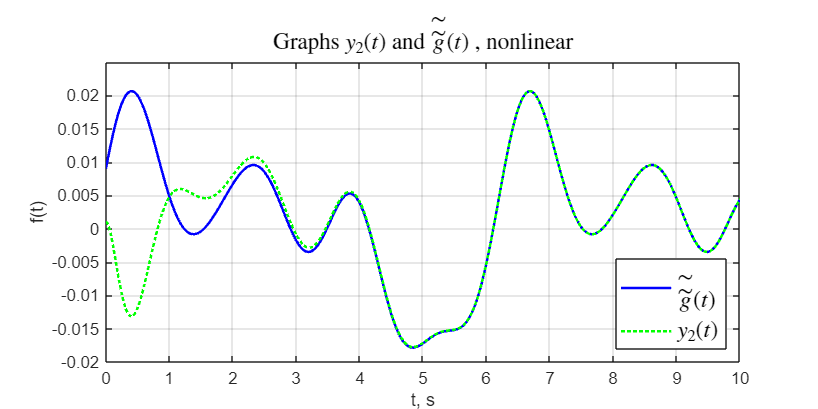

gg = sin(0.5*ti) + 0.8*sin(ti+pi/4)+0.6*sin(1.5*ti+pi/3)+0.4*sin(2*ti-pi/4)+0.2*sin(2.5*ti+pi/6);

x_sys = x(:,1:4);      % Основные состояния
w = x(:,5:14);
gh = Y_g*w';
%plot(t, x_sys(:,1))
%hold on
%plot(t, gh)
%plot(ti, gg)

figure('Position', [100 100 800 400])

%subplot(2,1,1);
plot(t, gh,'b-', 'LineWidth',1.5);
hold on
plot(t, x_sys(:,3),'g:', 'LineWidth',1.5);
legend('$\tilde{\tilde{g}}(t)$','$y_2(t)$' ,'Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 10]);
grid()
title('Graphs $y_2(t)$ and $\tilde{\tilde{g}}(t)$ , nonlinear','Interpreter','latex',  'FontSize', 14)
hold off

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\pic_fix' ...
    '\5_g_nonlin_another_an.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

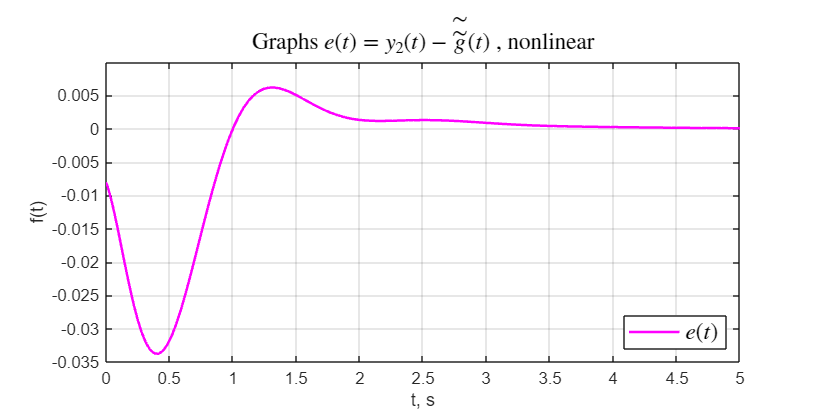

e = x_sys(:,3)-gh';
plot(t, e,'m', 'LineWidth',1.5);
legend('$e(t)$' ,'Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 5]);
grid()
title('Graphs $e(t) = y_2(t)-\tilde{\tilde{g}}(t)$ , nonlinear','Interpreter','latex',  'FontSize', 14)
hold off
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\pic_fix' ...
    '\5_g_nonlin_another_e_an.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);


% Извлечение результатов
%g = Y_g * x(:,5:end)';    % Сгенерированный сигнал
%u = x(:,1:4) * K' + x(:,5:end) * K_g;

%plot(t, C*x(:,2));


%====== Моделирование линейной=====

%{
open_system('task_5_f_lin');
set_param('task_5_f_lin/g_', 'VariableName', 'g_')
set_param('task_5_f_lin/y', 'VariableName', 'y')
out = sim('task_5_f_lin');

figure('Position', [100 100 800 400])

plot(out.y.Time, out.y.Data(:,2)-out.g_.Data(:,1),'m', 'LineWidth',1.5);
legend('$e(t)$' ,'Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()
title('Graph $e(t) = y(t) - g(t)$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\5_e_lin.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

%}
%subplot(2,1,1);
%{
plot(out.g_,'b-', 'LineWidth',1.5);
hold on

plot(out.y.Time, out.y.Data(:,2),'g:', 'LineWidth',1.5);
legend('$g(t)$','$y_2(t)$' ,'Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()
title('Graph $y(t)$ and $g(t)$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\5_g_lin.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

%}


%==========Компенсация=======
%{
for i=1:10
    disp(eig_G_f(i));
    ch_m = [A+B*K-I*eig_G_f(i), B;
        C_, 0]
    ch_r = rank(ch_m);
    disp(ch_r);
end
%}


%{
cvx_begin sdp
variable Pf(4, 10)
variable Kf(1, 10)

Pf*Gamma_f-(A+B*K)*Pf-D*Yf == B*Kf;
C_*Pf == 0;

cvx_end

Kf


[t, x] = ode45(@(t,x) pendulum_ode_with_compensation(t,x,K,Kf,Gamma_f,Yf,m,M,l,g), ...
              [0 5], [x_0; w_0]);

x_sys = x(:,1:4);      % Основные состояния
w = x(:,5:14);
%plot(t, x_sys(:,3))

%===============Моделирование нелинейной

figure('Position', [100 100 800 400])

%subplot(2,1,1);
plot(t, x_sys(:,1),'b-', 'LineWidth',1.5);
hold on
plot(t, x_sys(:,3),'c-', 'LineWidth',1.5);
legend('$y_1(t)$','$y_2(t)$' ,'Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()
title('Graph $y(t)$, nonlinear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\5_f_nonlin_1.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

%}


%========Моделирование линейной ========
%{
open_system('task_5_f_lin');
set_param('task_5_f_lin/f_', 'VariableName', 'f_')
set_param('task_5_f_lin/y', 'VariableName', 'y')
out = sim('task_5_f_lin');

figure('Position', [100 100 800 400])

subplot(2,2,1);
plot(out.y.Time, out.y.Data(1,:),'b-', 'LineWidth',1.5);

legend('$y_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
grid()


subplot(2,2,2);
plot(out.y.Time, out.y.Data(2,:),'c-', 'LineWidth',1.5);
legend('$y_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlim([0 5])
xlabel('t, s')
grid()

subplot(2,2,[3 4]);
plot(out.y.Time,out.f_.Data,'g-', 'LineWidth',1.5);
legend('$f(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graph $y(t)$ and $f(t)$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\5_f_lin.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);
%}
